close; clear; clc;

## Zadání

1.  Vytvořit Program_BC, který postupně načte všechny nahrávky a provede s nimi operace

- přidání malého šumu,

- filtrace

- segmentace na framy

- výpočet 2 jednoduchých příznaků. 

2. Pro načtení signálu používejte funkce AUDIOREAD, např. [x, Fs] = audioread („c0_p0123_s01.wav“, ‘native’).

TEST: Signál zobrazte a přehrajte.

3. V dalším kroku k signálu přičtěte malý šum

např. x = x + (randi(3, 32000, 1, 'int16') - 2); a signál následně zfiltrujte filtrem FIR xf = filter ([1 -0.97], 1, x)

TEST: Signál zobrazte a přehrajte.

4. Nyní signál rozdělte na framy dlouhé 25 ms, které se částečně překrývají. Framy začínají každých 10 ms

5. Vypočítáte pro každý frame hodnoty E a ZCR a jejich průběh zobrazíte v diagramu.

6. Na základě průběhu E naleznete framy kde slovo začíná a končí a v diagramu je vyznačíte svislou čárou.

TEST: Program následně vyřízne část signálu odpovídající slovu a toto přehraje. Tímto způsobem projděte všechny nahrávky a ověřte si, že nalezené hranice slova jsou správné. Pokud tomu tak není, změňte nastavení hodnoty prahu.

%Známé výchozí hodnoty
fs = 16000;% Vzorkovací frekvence (16 kHz)
p = 2502; % přidělené číslo
dir = fullfile(pwd, sprintf('p%d', p)); % cesta k adresáři
%threshold = -4;

i_max=5; % 5 nahrávek
c_max=10; % nahraná čísla 0-9

figure;
tiledlayout(i_max, c_max);

for i = 1:i_max
    fprintf("Nahrávka %0d",i)
    for c = 1:c_max
        % s_num = ceil(c / 10); % Určení čísla sXX
        file_name = sprintf('%s/c%d_p%d_s%02d.wav', dir, c-1, p, i);


        if exist(file_name, 'file')
            [recording, x_fs] = audioread(file_name);
        else
            warning("Soubor %s nebyl nalezen!", file_name);
            break;
        end

        if fs ~= x_fs
            warning("Neodpovídající vzorkovací frekvence %s", file_name);
            break;
        end

Nahrávka 1Nahrávka 2Nahrávka 3Nahrávka 4Nahrávka 5

TEST: Zobrazí a přehraje signál

        % figure;
        % plot(recording);
        % title('Originální signál');
        % sound(recording, fs);
        % pause(1);

## Přičtení malé náhodné hodnoty [-1 1] aby nedošlo k výpočtu 0 logaritmu.

        noise_level = 0.01 * std(recording); % adaptivní šum podle směrodatné odchylky
        recording = recording + (2 * rand(length(recording), 1) - 1) * noise_level;

## Filtrování horní propustí pro odstranění stejnosměrné složky ze signálu.

        rec_f = filter([1 -0.97], 1, recording);

TEST: Zobrazí a přehraje filtrovaný signál

        % figure;
        % plot(rec_f);
        % title('Filtrovaný signál');
        % sound(rec_f, fs);
        % pause(1);

## **Segmentace na framy (25 ms s 10 ms krokem)**

        frame_length = round(fs * 0.025); % 25 ms
        frame_step = round(fs * 0.01); % 10 ms
        num_frames = floor((length(rec_f) - frame_length) / frame_step) + 1;
        frames = zeros(frame_length, num_frames);

        for j = 1:num_frames
            start_idx = (j - 1) * frame_step + 1;
            end_idx = start_idx + frame_length - 1;
            frames(:, j) = rec_f(start_idx:end_idx);
        end

## Výpočet energie pro každý frame

        energy = log_energy(frames);

## Detekce slov na základě energie (práh)

        %% Dynamické nastavení prahu energie
        threshold = mean(energy) + 0.5 * std(energy);

        word_start = find(energy > threshold, 1, 'first');
        word_end = find(energy > threshold, 1, 'last');

        if ~isempty(word_start) && ~isempty(word_end)
            % fprintf('Začátek slova = %d, Konec slova = %d\n', word_start, word_end);

## Výpočet ZRC pro framy obsahující slovo

            % Vyříznutí slova
            start_sample = (word_start - 1) * frame_step + 1;
            end_sample = min(start_sample + (word_end - word_start) * frame_step + frame_length - 1, length(rec_f));
            word_segment = rec_f(start_sample:end_sample);
            % Z = ZCR(word_segment);

## Vizualizace

            nexttile;
            % yyaxis left;
            plot(energy, 'b');hold on;
            % ylabel('Log energie');
            

            % yyaxis right;
            % plot(Z, 'r'); 
            % ylabel('ZCR');
            title(sprintf('Nahrávka c%02d s%02d', c, i));
            % Zobrazení mezí v grafu
            % yyaxis left;
            xline(word_start, '--g');
            xline(word_end, '--r');
            hold off;

TEST: Přehraje slovo

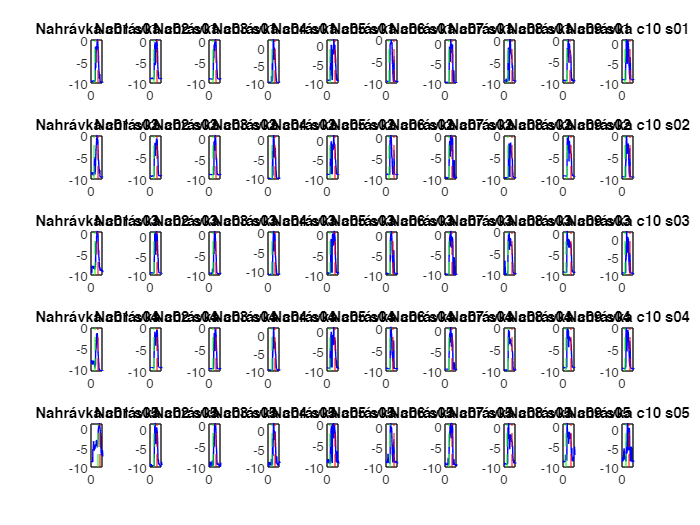

            % sound(word_segment, fs);
            % pause(1); % Pauza mezi přehrávkami
        end
    end
end